% 6.869 Advances in Computer Vision
% PSET 1
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

close all
clear all

## World paramaters

alpha = 35*pi/180;

## Load image

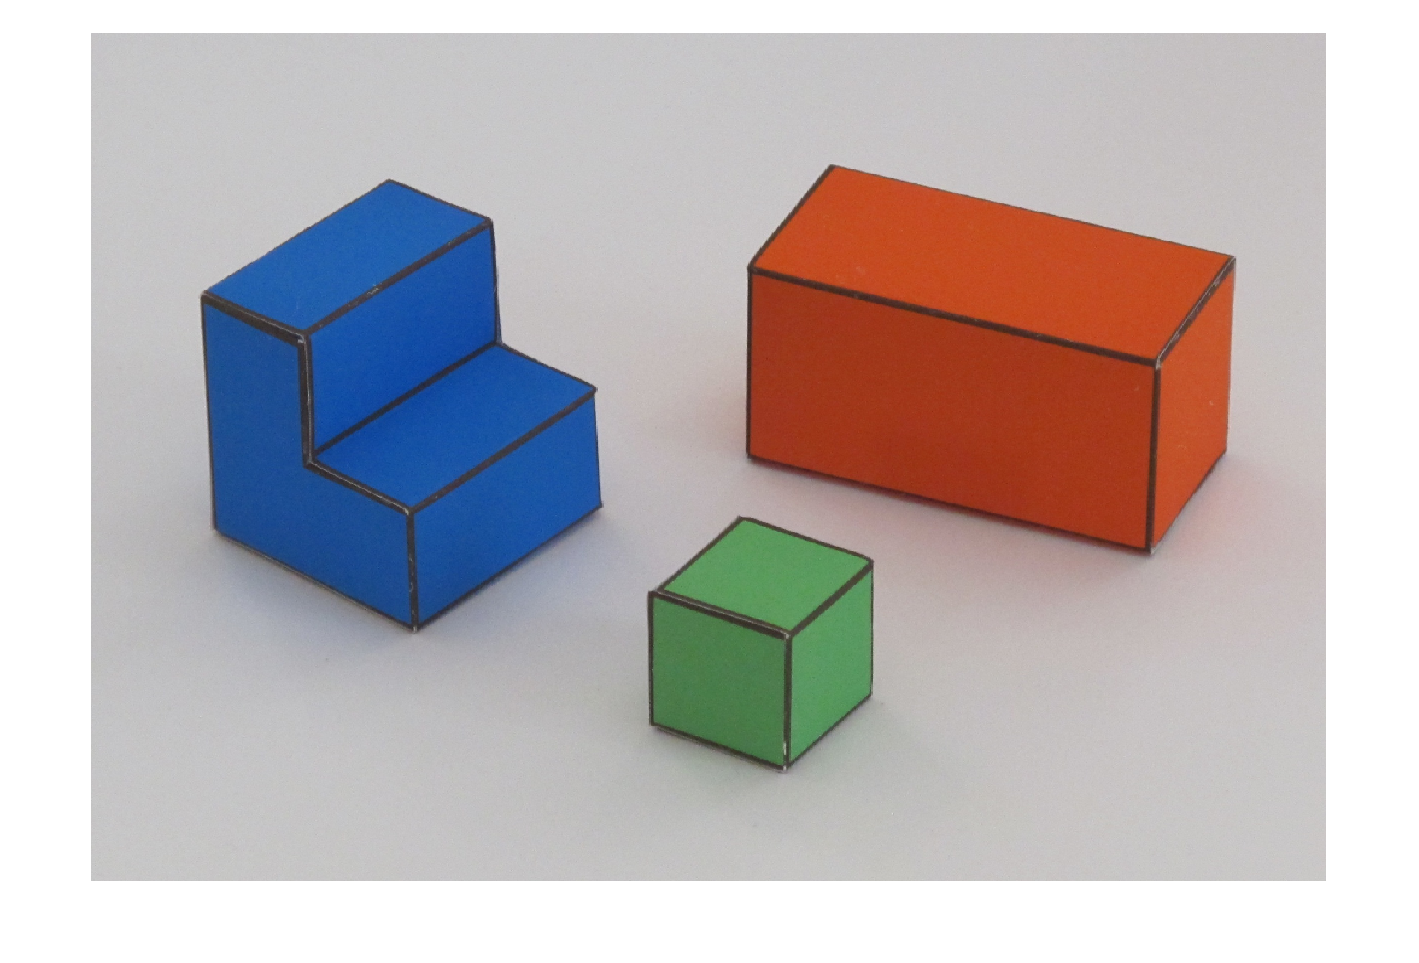

img = imread('img1.jpg'); %读入图片

imshow(img)

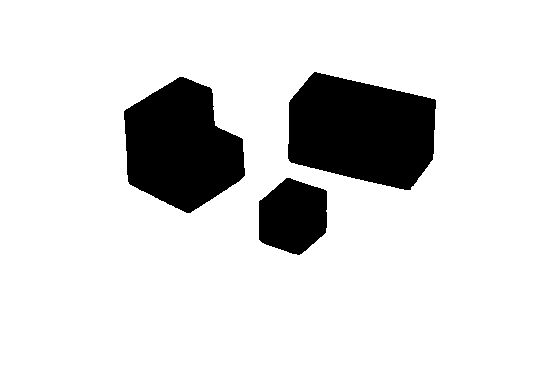

img = double(imresize(img, [256 NaN], 'bilinear')); %resieze 成行为256， 使用双线性插值
[nrows,ncols,colors] = size(img); %取出resize后的img

% Figure/ground separation 图像和背景的分割
ground = double(min(img,[],3)>110); %对每个像素点，取三通道的最小值进行二值化处理(背景为1，前景为0)
imshow(ground)

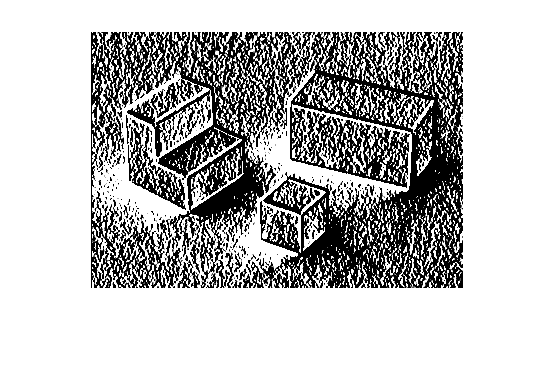

foreground = double(ground==0);%前景为1，背景为0

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Extract edges and orientations
m = mean(img,3); %图像按照三通道平均算出灰度图，dimension = 3 代表在通道轴上取平均
dmdx = conv2(m, [-1 0 1; -2 0 2; -1 0 1], 'same'); %二维图像卷积运算，应该是找竖的边缘
imshow(dmdx)

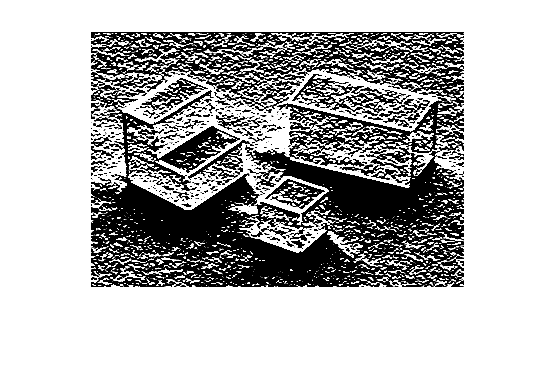

dmdy = conv2(m, [-1 0 1; -2 0 2; -1 0 1]', 'same'); %一撇是矩阵转置，找横的边缘
imshow(dmdy)

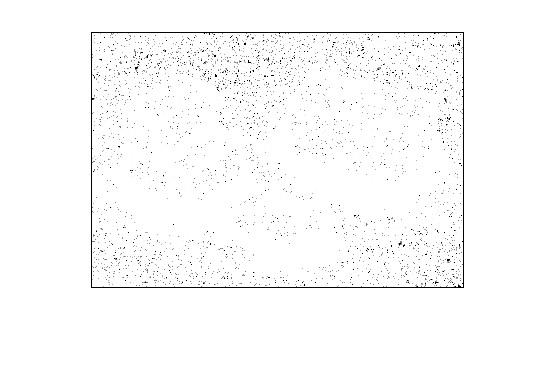

% Edge strength 边缘强度图
mag = sqrt(dmdx.^2+dmdy.^2); %矩阵每个像素上 边缘加权
mag(1:end,1)=0;
mag(1,1:end)=0;
mag(1:end,end)=0;
mag(end,1:end)=0;
imshow(mag)

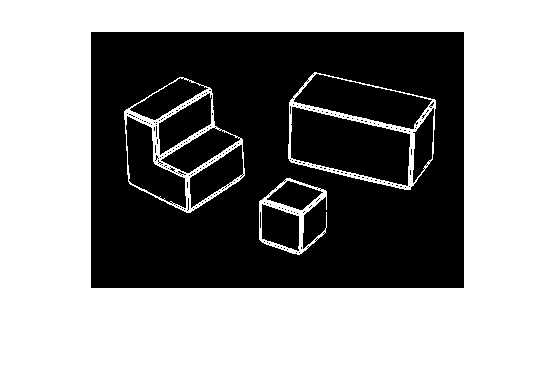

%四条边重置为0

% Edge orientation
theta = atan2(dmdx, dmdy); %得到边缘的角度

edges = mag>30; %二值化
%imshow(edges)
% Who owns the boundaries? the ground owns no boundaries. We set to zero
% all edges inside the ground.
edges = edges.*foreground;  %前景掩膜使得边缘变细变正常

imshow(edges)

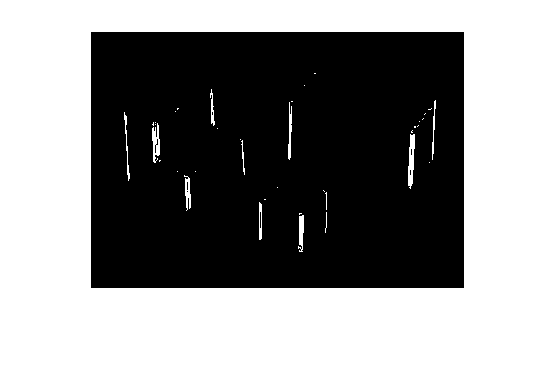

% Classify orientation
vertical_edges = edges.*((theta<115*pi/180).*(theta>65*pi/180)+(theta<-65*pi/180).*(theta>-115*pi/180)); %[65,115], [-115,-65]的成分，矩阵（非图像）掩膜，操作真高级
horizontal_edges = edges.*(1-vertical_edges); %除去垂直边的，都是水平边
imshow(vertical_edges)

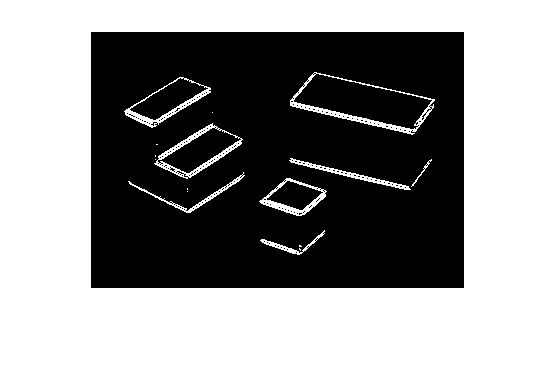

imshow(horizontal_edges)

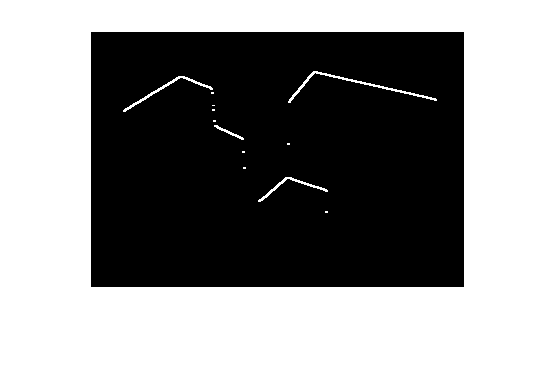


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Occlusion and contact edges
%    vertical edges separating an horizontal surface from a vertical surface are occlusion boundaries
%    把一个水平面从垂直面分离的垂直边就是阻碍边
%    edges between the ground and horizontal surfaces
%    在地面和水平平面之间的边缘
%    ground to foreground transitions (from top to botom) are occlusion
%    背景到前景的转换是阻碍边
horizontal_ground_to_foreground_edges = (conv2(double(ground==1), [-1 -2 -1; 0 0 0; 1 2 1], 'same'))>0;
%阻碍边=前景和背景之间的过渡区域= 前景找垂直边 / 水平边
imshow(horizontal_ground_to_foreground_edges) %显示水平阻碍边

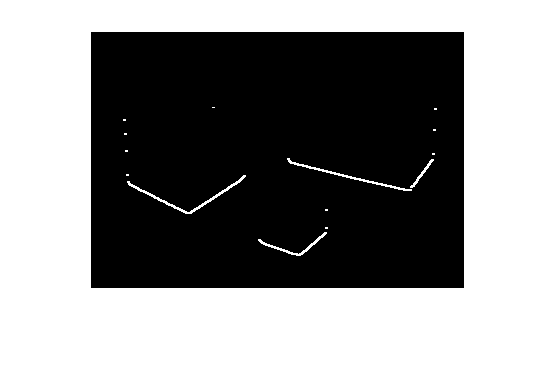

horizontal_foreground_to_ground_edges = (conv2(double(ground==0), [-1 -2 -1; 0 0 0; 1 2 1], 'same'))>0; %连接边
imshow(horizontal_foreground_to_ground_edges) %显示连接边

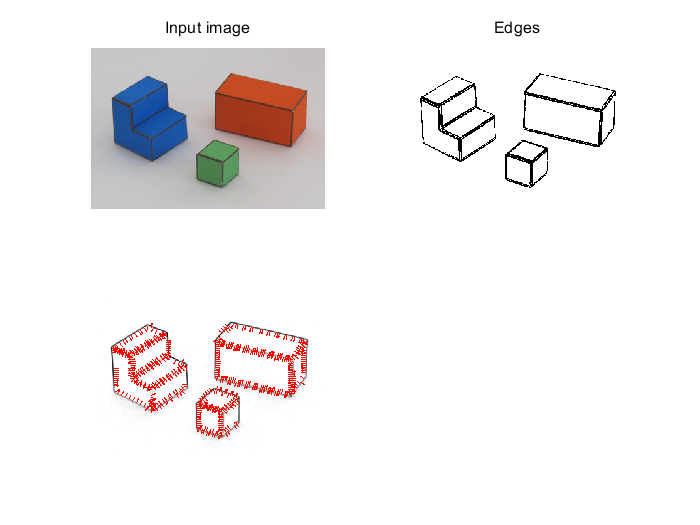

vertical_ground_to_foreground_edges = vertical_edges.*abs(conv2(double(ground==1), [-1 -2 -1; 0 0 0; 1 2 1]', 'same'))>0;
%垂直阻碍边
occlusion_edges = edges.*(vertical_ground_to_foreground_edges + horizontal_ground_to_foreground_edges); %阻碍边们
contact_edges   = horizontal_edges.*(horizontal_foreground_to_ground_edges); %连接边


E(:,:,1) = vertical_edges;
E(:,:,2) = horizontal_edges;
E(:,:,3) = zeros(size(occlusion_edges));

% edges and angles
figure
subplot(221)
imshow(uint8(img))
axis('off'); axis('equal')
title('Input image')
subplot(222)
imagesc(edges==0)
axis('off'); axis('equal')
title('Edges')
subplot(223)

% show normals
K = 3; % subsample
[ey,ex] = find(edges(1:K:end,1:K:end)); ey = (ey-1)*K+1; ex = (ex-1)*K+1;
imagesc(max(mag(:))-mag)
hold on
dxe = dmdx(sub2ind(size(dmdx), ey, ex));
dye = dmdy(sub2ind(size(dmdy), ey, ex));
n = sqrt(dxe.^2+dye.^2); 
dxe = dxe./n; dye = dye./n;
quiver(ex, ey, dxe, dye, .5, 'r');
axis('off'); axis('equal')
colormap(gray)
axis('ij')

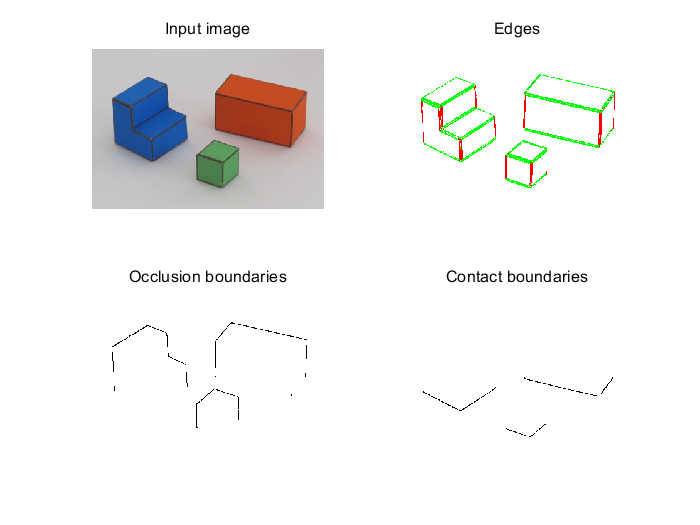



figure
subplot(221)
imshow(uint8(img))
axis('off'); axis('equal')
title('Input image')
subplot(222)
imagesc(E+repmat((edges==0), [1 1 3]))
axis('off'); axis('equal')
title('Edges')
subplot(223)
imagesc(1-(occlusion_edges>0))
axis('off'); axis('equal')
title('Occlusion boundaries')
colormap(gray)
subplot(224)
imagesc(1-contact_edges)
axis('off'); axis('equal')
title('Contact boundaries')
colormap(gray)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Initialize variables

Nconstraints = nrows*ncols*20; %约束方程数量
Aij = zeros([3 3 Nconstraints]);
ii = zeros([Nconstraints 1]);
jj = zeros([Nconstraints 1]);
b = zeros([Nconstraints 1]);

V = zeros([nrows ncols]);
% create linear constraints
c = 0;
for i = 2:nrows-1
    for j = 2:ncols-1 %枚举像素点
        if ground(i,j)==1 %是背景的情况
            % Y = 0;
            c = c+1; % increment constraint counter
            Aij(:,:,c) = [0 0 0; 0 1 0; 0 0 0];
            ii(c) = i; 
            jj(c) = j;
            b(c) = 1;
            V(i,j) = 0;
        else %是前景的情况
            % Check if current neirborhood touches an edge
            edgesum = sum(sum(edges(i-1:i+1,j-1:j+1))); %9邻域是否有边缘
            % Check if current neirborhood touches ground pixels %9领域是否有背景
            groundsum = sum(sum(ground(i-1:i+1,j-1:j+1)));
            % Check if current neirborhood touches vertical pixels %9邻域是否有垂直边
            vericalsum = sum(sum(vertical_edges(i-1:i+1,j-1:j+1)));
            % Check if current neirborhood touches horizontal pixels %9邻域是否有水平边
            horizontalsum = sum(sum(horizontal_edges(i-1:i+1,j-1:j+1)));
            % Orientation of edge (average over edge pixels in current
            % neirborhood)            
            dx = sum(sum(dmdx(i-1:i+1,j-1:j+1).*edges(i-1:i+1,j-1:j+1)))/edgesum;
            dy = sum(sum(dmdy(i-1:i+1,j-1:j+1).*edges(i-1:i+1,j-1:j+1)))/edgesum;
            orientation = atan2(dx, dy); %9邻域边缘平均方向

            if contact_edges(i,j)==1 %如果是接触边
                % dY/dy = 0
                c = c+1;   % increment constraint counter
                Aij(:,:,c) = [0 0 0; 0 1 0; 0 -1 0]; % kernel
                ii(c) = i; % image location
                jj(c) = j;
                b(c)  = 0; % desired output
            end
            if vericalsum>0 && groundsum==0 %物体内的垂直边
                % dY/dy = 1/cos a
                c = c+1; % increment constraint counter
                Aij(:,:,c) = [-1 -2 -1; 0 0 0; 1 2 1]/8;
                ii(c) = i; 
                jj(c) = j;
                b(c)  = 1/cos(alpha);
            end
            if horizontalsum>0 && groundsum==0 && vericalsum==0 %物体内的水平边
                % dY/dt = 0
                c = c+1; % increment constraint counter
                Aij(:,:,c) = ([-1, -2, -1;0, 0, 0;1, 2, 1])/8 * dx - ([-1, 0, 1;-2, 0, 2;-1, 0, 1])/8 * dy %!!!! FILL MISSING KERNEL HERE;
                ii(c) = i; 
                jj(c) = j;
                b(c)  = 0;
            end
            if groundsum==0 %剩下的情况（比如平坦区域）
                % laplacian = 0
                c = c+1; % increment constraint counter 
                Aij(:,:,c) = 0.1*[0 0 0; -1 2 -1; 0 0 0]; % (0.1 is a weight to reduce the strength of this constraint)
                ii(c) = i; 
                jj(c) = j;
                b(c) = 0;
                
                c = c+1; % increment constraint counter
                Aij(:,:,c) =0.1 * [0, -1, 0;0, 2, 0;0, -1, 0]% !!!! FILL MISSING KERNEL HERE;
                ii(c) = i; 
                jj(c) = j;
                b(c) = 0;
                
                c = c+1; % increment constraint counter
                Aij(:,:,c) = 0.1*[0 -1 1; 0 1 -1; 0 0 0];
                ii(c) = i; 
                jj(c) = j;
                b(c) = 0;
            end
        end
    end
end

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 

Aij = Aij(:,:,1) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,2) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,3) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,4) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,5) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,6) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,7) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,8) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,9) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,10) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,11) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,12) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,13) =

     0     0     0
     0     1     0
     0     0     0


Aij(:,:,14) =

     0     0     0
     0 


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Solve for Z
% Create sparse matrices
ii = ii(1:c); jj = jj(1:c); Aij = Aij(:,:,1:c); b = b(1:c);
A = sparseMatrix(ii, jj, Aij, nrows);
% Solve linear system
Y = A\b;

Y(nrows*ncols)=NaN; % make sure it has the right dimensions.
Y = reshape(Y, [nrows ncols]); % transform vector into an image


% Recover 3D world coordinates
[x,y] = meshgrid(1:ncols, 1:nrows);
x = x-ncols/2;
y = (y-nrows/2);

X = x;
Z = Y*cos(alpha)/sin(alpha) -  y/sin(alpha);
Y = -Y;

Y(Y<0)=0;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Visualization
figure
subplot(221)
imshow(uint8(img(2:end-1, 2:end-1,:)));
subplot(222)
imagesc(Z(2:end-1, 2:end-1))
title('Z (depth)')
axis('equal'); axis('off')
subplot(223)
imagesc(Y(2:end-1, 2:end-1))
axis('equal'); axis('off')
title('Y (height)')
subplot(224)
imagesc(X(2:end-1, 2:end-1))
axis('equal'); axis('off')
title('X')
colormap(gray)

## Render image

E = double(occlusion_edges);
E (find(E))=NaN;
Z = Z+E; % remove occluded edges

figure
surf(X(2:end-1, 2:end-1),Z(2:end-1, 2:end-1),Y(2:end-1, 2:end-1), double(img(2:end-1, 2:end-1, :))/256)
axis('equal')
shading flat